# Using Matlab to Access OOI Data from THREDDS and ERDDAP

The following code examples provide a basic set of tools a user could use to access data from the OOI THREDDS and ERDDAP servers using Matlab. This example is specifically focused on the [OOI Gold Copy THREDDS catalog](https://thredds.dataexplorer.oceanobservatories.org/thredds/catalog/ooigoldcopy/public/catalog.html), the [Data Explorer ERDDAP](https://erddap.dataexplorer.oceanobservatories.org/erddap/index.html) (and by extension the OOI Glider data available from the GliderDAC). These are basic functions intended to show how a user could use Matlab to access OOI data from either the [OOI Gold Copy THREDDS catalog](https://thredds.dataexplorer.oceanobservatories.org/thredds/catalog/ooigoldcopy/public/catalog.html), or the [Data Explorer ERDDAP](https://erddap.dataexplorer.oceanobservatories.org/erddap/index.html) server. By no means are these meant to be an exhaustive respresentation covering every variant of the data and/or the different issues one might encounter with the different data sources. Hopefully, however, these will provide a user with some starting blocks from which they can develop their own set of tools to access the data.

## Finding the Data

OOI data is organized according to the Reference Designator, data delivery method and the data stream name. For most of this example, we will be working with data from the dissolved oxygen sensor on the midwater platform (aka Near-Surface Instrument Frame (NSIF) at 7 m) of the Coastal Endurance Oregon Inshore Surface Mooring (`CE01ISSM-RID16-03-DOSTAD000`). We'll use the `telmetered` data contained in the `dosta_abcdjm_ctdbp_dcl_instrument` stream. You can find a list of available reference designators and streams starting from the [site list](https://oceanobservatories.org/site-list/) maintained by OOI.

% setup defaults to use in subsequent data queries
refdes = "CE01ISSM-RID16-03-DOSTAD000";
method = "telemetered";
stream = "dosta_abcdjm_ctdbp_dcl_instrument";

% construct the OOI Gold Copy THREDDS catalog URL for this data set
base_url = "https://thredds.dataexplorer.oceanobservatories.org/thredds/catalog/ooigoldcopy/public/";
url = join([base_url, join([refdes, method, stream], '-'), '/catalog.html'], '');
url

url = "https://thredds.dataexplorer.oceanobservatories.org/thredds/catalog/ooigoldcopy/public/CE01ISSM-RID16-03-DOSTAD000-telemetered-dosta_abcdjm_ctdbp_dcl_instrument/catalog.html"

## Listing Data Files

We can use the `webread` function to scrape the above catalog URL for the data files of interest. To do that, we need to create a simple function using the above URL as an input and a regex tag that can be used to specify the specific files we are after. Because this is Matlab, we need to put that function at the bottom of this script so it can be used as a local function. You'll need to scroll down to the section of local functions to see the contents of the `list_files` function.

### Constructing the tag

The tag can be used in many ways. A simple tag like `'.*\.nc$'` would list all of the netCDF files in the catalog. Because the DOSTA requires data from a co-located CTD (temperature and salinity), there are CTDBP files present in the catalog as well. Since we don't want those, we can change our tag to be more exclusive (e.g., `'.*DOSTA.*\.nc$'`). That tag would then list every DOSTA netCDF file in the catalog. If we were after just the files from Deployment 15, then we can tweak the tag a little further (`'deployment0015.*DOSTA.*\.nc$'`).

tag = 'deployment0015.*DOSTA.*\.nc$';
nc_files = list_files(url, tag);
nc_files(1)

ans = "deployment0015_CE01ISSM-RID16-03-DOSTAD000-telemetered-dosta_abcdjm_ctdbp_dcl_instrument_20210917T153121.389000-20220330T203024.367000.nc"

## Loading Data

We can use either `websave` or the Matlab NetCDF utilites and the OpenDAP server to download netCDF file(s) from the list, and then load the contents into user space. Either option will work. Below, we will use `websave` to download one of the data files to a local file called `data.nc`.  

file_url = 'https://thredds.dataexplorer.oceanobservatories.org/thredds/fileServer/ooigoldcopy/public/';
[~, file, ext] = fileparts(nc_files(1));
nc_url = join([file_url, join([refdes, method, stream], '-'), '/', file, ext], '');
websave('data.nc', nc_url);

% use custom developed nc_reader script (see Local Functions below) to load the
% netCDF file in as a timetable
data = nc_reader('data.nc');
data(1:10, {'dissolved_oxygen', 'sea_water_temperature', 'sea_water_practical_salinity'})

ans = 10×3 timetable
            Time            dissolved_oxygen    sea_water_temperature    sea_water_practical_salinity
    ____________________    ________________    _____________________    ____________________________

    17-Sep-2021 15:31:21         95.952                8.2944                        33.83           
    17-Sep-2021 16:31:18         84.538                8.2846                       33.834           
    17-Sep-2021 17:31:19         99.902                8.3612                       33.825           
    17-Sep-2021 18:31:20         110.83                8.4423                       33.817           
    17-Sep-2021 20:30:13         164.53                9.0443                        33.79           
    17-Sep-2021 22:30:13  

% use a for-loop to download all the data files and create a single timetable
% for all of deployment 15
nfiles = numel(nc_files);
data = cell(nfiles, 1);     % pre-allocate an empty cell array for downloaded results
for i = 1:nfiles
    file = join([file_url, join([refdes, method, stream], '-'), '/', nc_files(i)], '');
    websave('data.nc', file);
    data{i} = nc_reader('data.nc');
end %for
clear i file
delete('data.nc')
data = cat(1, data{:});

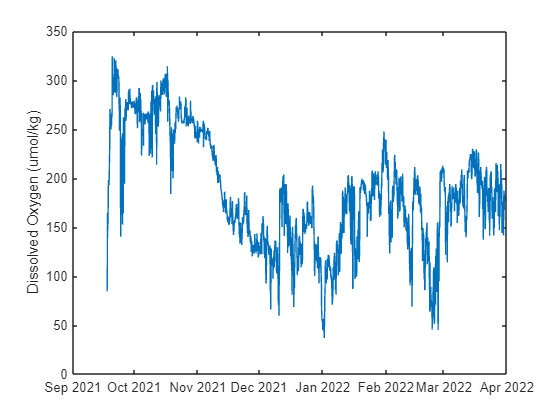

% plot the pressure and salinity corrected dissolved oxygen concentration
% measurements telemetered during deployment 15
plot(data.Time, data.dissolved_oxygen)
ylabel('Dissolved Oxygen (umol/kg)')

## Data Explorer ERDDAP

The same data is available from the [OOI Data Explorer ERDDAP](https://erddap.dataexplorer.oceanobservatories.org/erddap/index.html) server. We use similar tools (websave) to load that data into the workspace for further analysis. ERDDAP supports several data formats for data access, including `.mat` files which can then be loaded directly into Matlab. The user will need to interface with the [OOI Data Explorer ERDDAP](https://erddap.dataexplorer.oceanobservatories.org/erddap/index.html) server to identify the dataset of interest, the desired data parameters and a time range of interest. Once those are identified, the request can be constructed using a simple function (see `erddap_load` below):

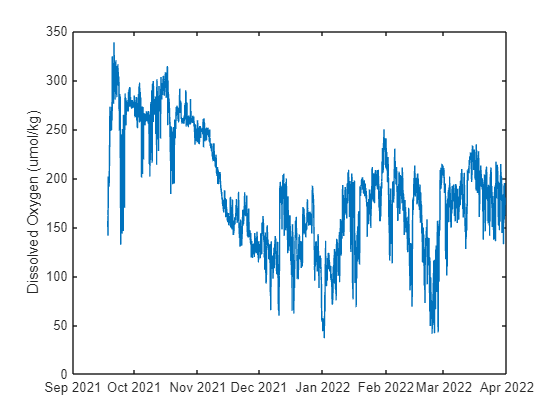

% Dataset ID is based on the reference designator with 'ooi-' prepended
dataset_id = 'ooi-ce01issm-rid16-03-dostad000';
% variable(s) is a comma separated list (time is always added)
variables = 'moles_of_oxygen_per_unit_mass_in_sea_water,sea_water_practical_salinity,sea_water_temperature';
times = [   % needs to be formatted as below, with a start and end date
    string(datetime(2021, 09, 18), 'yyyy-MM-dd''T''HH:mm:ss''Z''')
    string(datetime(2022, 03, 31), 'yyyy-MM-dd''T''HH:mm:ss''Z''')
    ];

edata = erddap_load(dataset_id, variables, times);

% plot the data
plot(edata.time, edata.moles_of_oxygen_per_unit_mass_i)
ylabel('Dissolved Oxygen (umol/kg)')

## Local Functions

function nc_files = list_files(url, tag)
% Function to create a list of the netCDF data files in the THREDDS catalog
% Inputs are the URL for the THREDDS catalog of interest and a regex tag
% used to subselect only the netCDF files of interest

% use webread to scrape the catalog
catalog = webread(url);

% pull a list of netCDF files out of the catalog
nc_all = regexp(catalog, '<a href=''([^>]+.nc)''>', 'tokens');

% cell elements are themselves cells, convert to cell array of character vectors
nc_all = [nc_all{:}]';

% drop 'catalog.html?dataset=' from URL
nc_all = cellfun(@(x) x(22:end), nc_all, 'UniformOutput', 0); %

% use the regex tag to select only files of interest
nc_all = cellfun(@(x) regexp(x, tag, 'match'), nc_all, 'UniformOutput', 0);
nc_all(cellfun('isempty', nc_all)) = [];  % remove empty matches

% convert the list to a string array
nc_files = string(nc_all(:));
end %function


function t = nc_reader(filename)
% NC_READER Read a NetCDF file, extracting all variables (with a few
% exceptions), saving the results in a timetable.
% 
% Code based on example available from Mathworks at:
% https://www.mathworks.com/help/parallel-computing/examples/process-big-data-in-the-cloud.html

% Get information about the NetCDF data file
fileInfo = ncinfo(filename);

% Extract the global and variable level attributes -- note, Matlab doesn't
% really support these very well, so their utility is limited.
%gAttributes = struct2table(fileInfo.Attributes);
vAttributes = {fileInfo.Variables.Attributes};

% Extract the variable names
varNames = string({fileInfo.Variables.Name});

% test for presence of a variable called time
i = 1; test = 0;
while test == 0 && i <= numel(varNames)
    test = strcmp('time', varNames{i});
    i = i + 1;
end %while
if ~test
    error('The NetCDF file specified does not include the variable ''time''')
end %if
clear test

% use the time variable metadata to set the rowtimes for the timetable
attr = struct2table(vAttributes{i-1}); clear i
units = "";
for j = 1:height(attr)
    if strcmp(attr.Name(j), 'units')
        units = string(attr.Value(j));
    end %if
end %for
if units == ""
    % no units are defined for time (this is extremely unlikely)
    error(['The NetCDF file has a time variable, but the units are ' ...
        'undefined. Unable to create a rowtime variable for the data.']);
end %if

% create a file ID used to read data from the file
ncid = netcdf.open(filename, 'NOWRITE');

% Create the datetime axis from the time variable (ERDDAP uses
% 1970, while the OOI-created NetCDF files use 1900 as their pivot years).
%nc_time = h5read(filename, '/time');   % obtain the time record
nc_time = netcdf.getVar(ncid, netcdf.inqVarID(ncid, 'time'));
test = seconds(nc_time(1)) + datetime(1970, 1, 1, 0, 0, 0);
if test > datetime("now")
    dt = datetime(nc_time, 'ConvertFrom', 'epochtime', 'Epoch', '1900-01-01', 'TimeZone', 'UTC');
else 
    dt = datetime(nc_time, 'ConvertFrom', 'epochtime', 'Epoch', '1970-01-01', 'TimeZone', 'UTC');
end %if
rowlength = length(dt);
clear test nc_time

% Create an empty timetable using the datetime axis
t = timetable('RowTimes', dt);

% Populate the timetable with the variable data
for k = 1:numel(varNames)
    % skip adding time (already added as the RowTime) and obs
    if strcmp(varNames{k}, 'time') || strcmp(varNames{k}, 'obs')
        continue
    end %if
    % read the variable from the NetCDF file
    %data = squeeze(h5read(filename, "/" + varNames{k}));
    data = squeeze(netcdf.getVar(ncid, netcdf.inqVarID(ncid, varNames{k})));
    % pull out the variable units and comment attributes
    if ~isempty(vAttributes{k})
        attr = struct2table(vAttributes{k});
        units = {''}; descr = {''};
        for j = 1:height(attr)
            if strcmp(attr.Name(j), 'units')
                units = attr.Value(j);
            end %if
            if strcmp(attr.Name(j), 'comment')
                descr = attr.Value(j);
            end %if
        end %for
    end %if
    % add the variable and attributes to the time table
    [r, c] = size(data);    % check the dimensions 
    if r == rowlength
        % if the number of rows == the number of RowTimes, add the variable
        % without modification.
        if strcmp(fileInfo.Variables(k).Datatype, 'char')
            t = addvars(t, deblank(data), 'NewVariableNames', varNames{k});
        else
            t = addvars(t, data, 'NewVariableNames', varNames{k});
        end %if
        t.Properties.VariableUnits{varNames{k}} = units{:};
        t.Properties.VariableDescriptions{varNames{k}} = descr{:};
    elseif c == rowlength
        % if the number of columns equals the RowTimes, rotate the variable
        % before adding it so the row length matches the RowTimes
        if strcmp(fileInfo.Variables(k).Datatype, 'char')
            t = addvars(t, deblank(data'), 'NewVariableNames', varNames{k});
        else
            t = addvars(t, data', 'NewVariableNames', varNames{k});
        end %if
        t.Properties.VariableUnits{varNames{k}} = units{:};
        t.Properties.VariableDescriptions{varNames{k}} = descr{:};
    elseif r == 1 && c == 1
        % this is a scalar variable, and it needs to replicated out to the
        % RowTimes dimension before it can be added.
        t = addvars(t, repmat(data, rowlength, 1), 'NewVariableNames', varNames{k});
        t.Properties.VariableUnits{varNames{k}} = units{:};
        t.Properties.VariableDescriptions{varNames{k}} = descr{:};        
    else
        % this is something weird, ignore it for now.
    end %if
end %for
netcdf.close(ncid);
clear ncid dt rowlength k data r c

% clean-up the timetable making sure the records are unique and sorted by time
t = unique(t, "rows");
end %function


function data = erddap_load(dataset_id, variables, times)
%
% ERDDAP_LOAD(dataset_id, variables, times)
%
% Simple example function showing how to download date from the OOI Data
% Explorer ERDDAP server. Users will need to know the Dataset ID, the 
% variable(s) of interest, and a time range to bound the size of the
% request.
%
% C. Wingard, 2021-12-20

% setup the request URL to download data from the Data Explorer ERDDAP
erddap_url = 'http://erddap.dataexplorer.oceanobservatories.org/erddap/tabledap';
url = [erddap_url '/' dataset_id '.mat?time,' variables '&time>=' char(times(1, :)) '&time<=' char(times(2, :))];

% download the data as a MAT file and load it
websave('temp.mat', url);
m = matfile('temp.mat');
data = m.(replace(dataset_id, '-', '_'));
delete('temp.mat')
clear url m

% convert the time record from seconds since 1970 to a Matlab datenum ...
%data.time = data.time / 86400 + 719529;

% ... or a datetime object
data.time = datetime(data.time, 'ConvertFrom', 'posixtime', 'TimeZone', 'UTC');

% convert the structured array to a timetable
data = table2timetable(struct2table(data),"RowTimes","time");
end %function